# ADACS Homework 3

By: $\underline{Dillon \ Allen}$

## Scenario

The equations governing a rigid body is


$$\frac{d}{dt} H = 0 \Longrightarrow \frac{d}{dt} \left( \left[I \right] \right) \omega = 0$$



$$\frac{d}{dt} \left( \left[ I \right] \omega \right) = \left[ I \right] \dot{\omega} + \omega \times \left( \left[ I \right] \omega \right)$$



$$\dot{\omega} = - \left[ I \right] ^{-1} \left( \omega \times \left( \left[ I \right] \omega \right)$$


## Problem 1

Expand the equations and write in the form


$$\frac{d}{dt} \omega = f \left(\omega, t\right)$$


Solution:


$$\left[I\right] \omega = \pmatrix{I_{x} & 0 & 0 \cr 0 & I_{y} & 0 \cr 0 & 0 & I_{z}} \pmatrix{\omega_{x} \cr \omega_{y} \cr \omega_{z}} = \pmatrix{I_x \omega_x \cr I_y \omega_y \cr I_z \omega_z}$$



$$\omega \times \left[I\right] \omega = \pmatrix{\omega_x \cr \omega_y \cr \omega_z} \times \pmatrix{ I_x \omega_x \cr I_y \omega_y \cr I_z \omega_z} = \pmatrix{\omega_y \omega_z \left(I_z - I_y\right) \cr \omega_x \omega_z \left( I_x - I_z \right) \cr \omega_x \omega_y \left( I_y - I_x\right)}$$



$$\left[ I \right]^{-1} = \pmatrix{\frac{1}{I_x} & 0 & 0 \cr 0 & \frac{1}{I_y} & 0 \cr 0 & 0 & \frac{1}{I_z}}$$



$$\frac{d}{dt} \omega = - \left[ I \right]^{-1} \left( \omega \times \left[ I \right] \omega \right)$$



$$\frac{d}{dt} \omega = \pmatrix{-I_x^{-1} & 0 & 0 \cr 0 & -I_y^{-1} & 0 \cr 0 & 0 & -I_z^{-1}} \pmatrix{\omega_y \omega_z \left(I_z - I_y \right) \cr \omega_x \omega_z \left(I_x - I_z\right) \cr \omega_x \omega_y \left(I_y - I_x\right)} = \pmatrix{\omega_y \omega_z \left(\frac{I_y - I_z}{I_x}\right) \cr \omega_x \omega_z \left( \frac{I_z - I_x}{I_y} \right) \cr \omega_x \omega_y \left( \frac{I_x - I_y}{I_z}\right)}$$


Thus, the three differential equations are


$$\dot{\omega}_{x} = \omega_y \omega_z \left( \frac{I_y - I_z}{I_x} \right)$$



$$\dot{\omega}_{y} = \omega_x \omega_z \left(\frac{I_z - I_x}{I_y}\right)$$



$$\dot{\omega}_{z} = \omega_x \omega_y \left( \frac{I_x - I_y}{I_z} \right)$$


## Problem 2

Write the expression for the magnitude of the total momentum (h) and the rotational kinetic energy (T)

Solution:

The equation for the total momentum is


$$\textbf{h} = \left[ I \right] \omega$$



$$\textbf{h} = \pmatrix{I_x \omega_x \cr I_y \omega_y \cr I_z \omega_z}$$



$$|\! | h |\!| = \sqrt{I_x^2 \omega_x^2 + I_y^2 \omega_y^2 + I_z^2 \omega_z^2}$$


The equation for the rotational Kinetic Energy is 


$$T_{\text{rot}} = \frac{1}{2} \omega^{T} \left[ I \right] \omega$$



$$T_{\text{rot}} = \frac{1}{2} \pmatrix{\omega_x & \omega_y & \omega_z} \pmatrix{I_x \omega_x \cr I_y \omega_y \cr I_z \omega_z} = \frac{1}{2} \left( I_x \omega_x^2 + I_y \omega_y^2 + I_z \omega_z^2 \right)$$


## Problem 3 (Function at bottom)

Run the problem for the following conditions

- [I] = diag([100,200,300])

- $\omega_x = 0$, $\omega_y = 1 \frac{\text{deg}}{\text{sec}}$, $\omega_z = 30\ \text{rpm}$

- time span of 20 seconds

And find the following:

- Plot the angular rates as a function of time

- Plot the total momentum and kinetic energy vs time

- Show the total momentum and kinetic energy are constant

- Show that the resulting motion is sinusoidal with period of about 2 seconds.

Solution:

% Initial Conditions
Imat1 = diag([100, 200, 300]);

w_initial1_x = 0;
w_initial1_y = 1 * (pi/180); % deg/s -> rad/s
w_initial1_z = 30 * (2*pi/60);  % rpm -> rad/s

w_initial1 = [w_initial1_x; w_initial1_y; w_initial1_z];

tspan1 = 0:0.1:20; % seconds

[w1, momenta_matrix1, totMomentum1, Trot1] = ... 

w1 =          0    0.0175    3.1416
   -0.0054    0.0166    3.1416
   -0.0103    0.0141    3.1416
   -0.0141    0.0103    3.1416
   -0.0166    0.0054    3.1416
   -0.0175   -0.0000    3.1416
   -0.0166   -0.0054    3.1416
   -0.0141   -0.0103    3.1416
   -0.0103   -0.0141    3.1416
   -0.0054   -0.0166    3.1416


momenta_matrix1 = 1×201 cell array
    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {

totMomentum1 = 1×201 cell array
    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[94

Trot1 = 1×201 cell array
    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}   

                      AngularRateODESolver(Imat1, w_initial1, tspan1)

% Peak Finding for Period
[~,locs] = findpeaks(w1(:,1),tspan1);
period = max(diff(locs))

period = 2

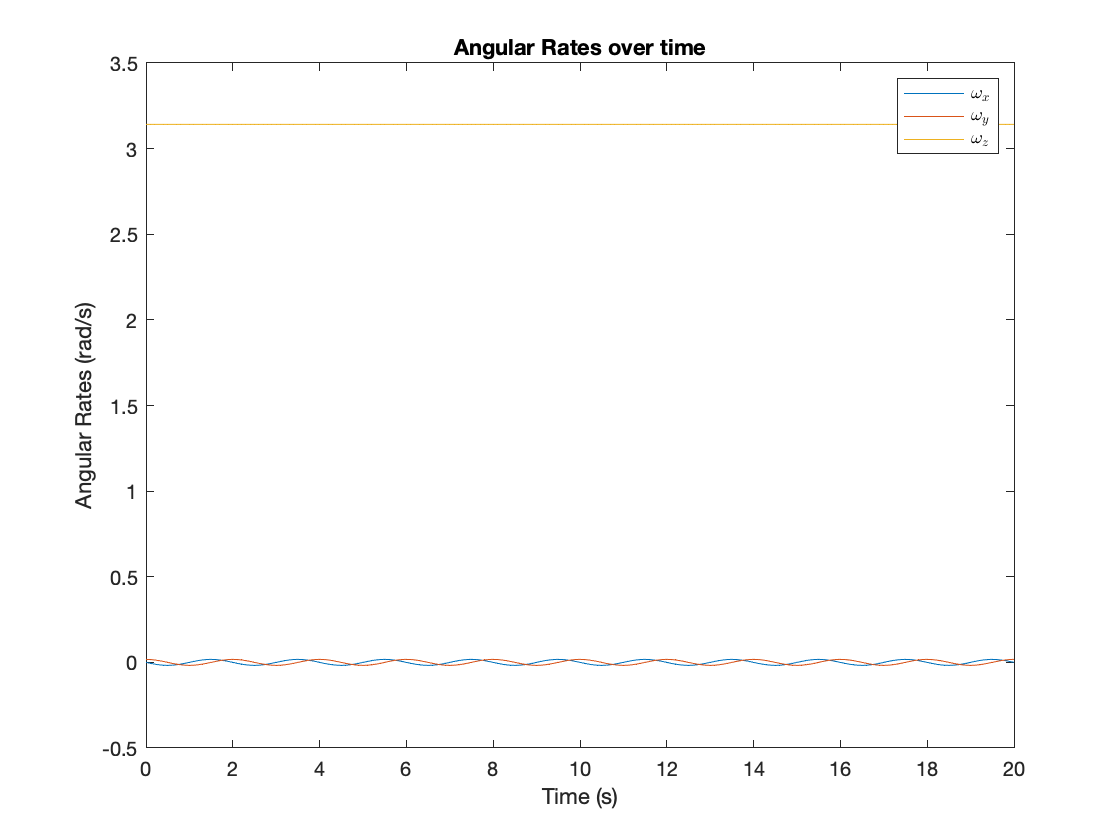

% Angular Rate Plot
figure(1)
plot(tspan1, w1(:,1));
hold on
plot(tspan1, w1(:,2));
plot(tspan1, w1(:,3));
hold off;
title("Angular Rates over time");
xlabel("Time (s)");
ylabel("Angular Rates (rad/s)");
legend("$\omega_x$", "$\omega_y$", "$\omega_z$", 'Interpreter',"latex")

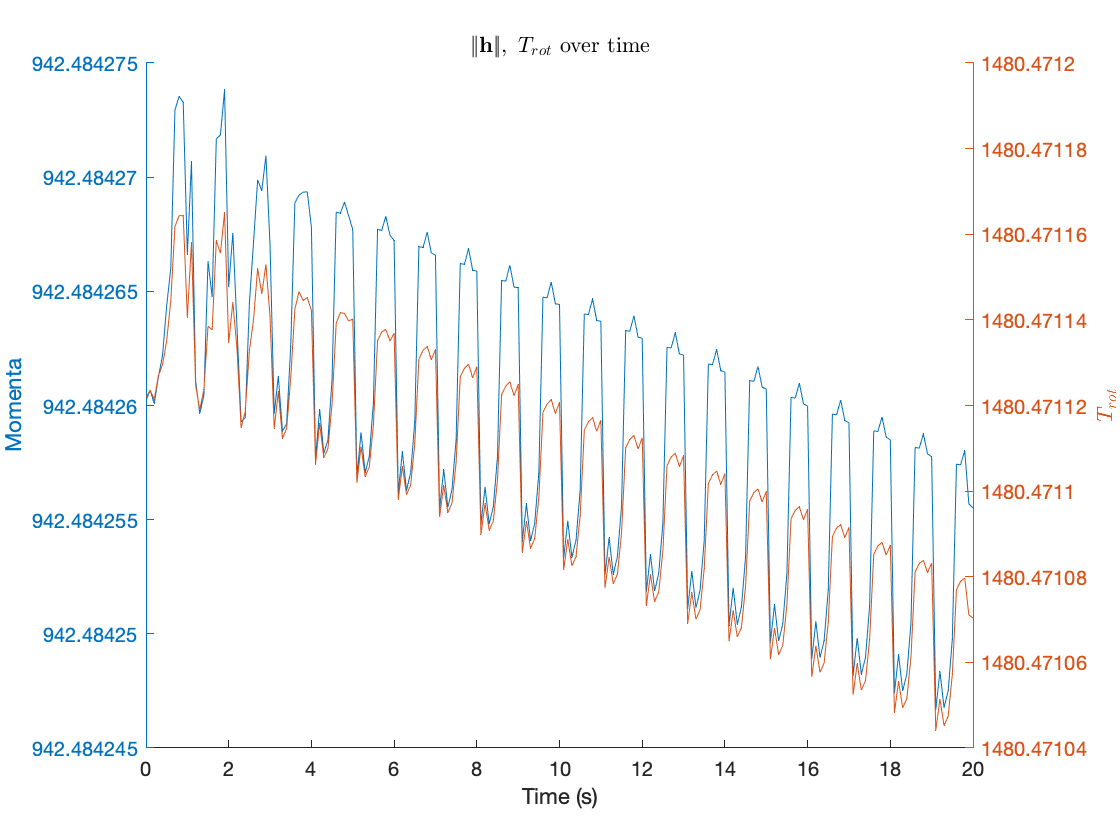

% Total Momentum and Kinetic Energy Plots

figure(2)
hold on
yyaxis left
plot(tspan1,cell2mat(totMomentum1))
ylabel("Momenta")
xlabel("Time (s)");
yyaxis right
plot(tspan1, cell2mat(Trot1));
ylabel("$T_{rot}$", "Interpreter","latex")
hold off;
title("$|\!| \textbf{h} |\!|,\ T_{rot} $ over time","Interpreter","latex")

## Problem 4

With the same body, re-run the simulation with new parameters:

- [I] = diag([100, 200, 300]);

- $\omega_x = 1 \frac{\text{deg}}{\text{sec}}$, $\omega_y = 30 \ \text{rpm}$, $\omega_z = 0$

- time span: 20 seconds

Solution:

% Initial Conditions

% Moment of Inertia Matrix
Imat2 = diag([100,200,300]);

% Initial Angular Rates
w_initial2_x = 1 * (pi/180); % deg/s -> rad/s
w_initial2_y = 30 * (2*pi/60); % rpm -> rad/s
w_initial2_z = 0;
w_initial2 = [w_initial2_x; w_initial2_y; w_initial2_z];

tspan2 = 0:0.1:20;

[w2, momenta_matrix2, totMomentum2, Trot2] = ...

w2 =     0.0175    3.1416         0
    0.0177    3.1416   -0.0018
    0.0186    3.1416   -0.0037
    0.0201    3.1416   -0.0058
    0.0223    3.1416   -0.0080
    0.0251    3.1415   -0.0104
    0.0289    3.1415   -0.0133
    0.0335    3.1415   -0.0165
    0.0393    3.1414   -0.0203
    0.0464    3.1413   -0.0248


momenta_matrix2 = 1×201 cell array
    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {

totMomentum2 = 1×201 cell array
    {[628.3210]}    {[628.3210]}    {[628.3210]}    {[628.3210]}    {[628.3210]}    {[628.3210]}    {[628.3209]}    {[628.3209]}    {[628.3210]}    {[628.3210]}    {[628.3208]}    {[628.3203]}    {[628.3206]}    {[628.3214]}    {[628.3217]}    {[628.3215]}    {[628.3154]}    {[628.3128]}    {[628.3189]}    {[628.3277]}    {[628.3309]}    {[628.3287]}    {[628.2717]}    {[628.2327]}    {[628.2758]}    {[628.3689]}    {[628.4378]}    {[628.4414]}    {[628.4496]}    {[628.4418]}    {[628.4241]}    {[628.4899]}    {[628.6133]}    {[628.7491]}    {[628.9246]}    {[628.7643]}    {[628.4539]}    {[628.3728]}    {[628.3574]}    {[628.4396]}    {[628.3939]}    {[628.1413]}    {[628.1486]}    {[628.1467]}    {[628.0762]}    {[628.0032]}    {[628.0342]}    {[628.0385]}    {[627.9941]}    {[627.9480]}    {[627.9363]}    {[627.9448]}    {[627.9410]}    {[627.9228]}    {[627.9077]}    {[627.9082]}    {[627.9089]}    {[627.9055]}    {[627.9008]}    {[627.8996]}    {[62

Trot2 = 1×201 cell array
    {[986.9757]}    {[986.9757]}    {[986.9757]}    {[986.9757]}    {[986.9757]}    {[986.9757]}    {[986.9755]}    {[986.9756]}    {[986.9758]}    {[986.9758]}    {[986.9751]}    {[986.9736]}    {[986.9746]}    {[986.9770]}    {[986.9780]}    {[986.9772]}    {[986.9583]}    {[986.9502]}    {[986.9691]}    {[986.9968]}    {[987.0071]}    {[987.0000]}    {[986.8208]}    {[986.6985]}    {[986.8337]}    {[987.1262]}    {[987.3427]}    {[987.3541]}    {[987.3800]}    {[987.3553]}    {[987.2999]}    {[987.5067]}    {[987.8944]}    {[988.3213]}    {[988.8730]}    {[988.3690]}    {[987.3933]}    {[987.1387]}    {[987.0901]}    {[987.3485]}    {[987.2049]}    {[986.4115]}    {[986.4343]}    {[986.4282]}    {[986.2071]}    {[985.9778]}    {[986.0751]}    {[986.0886]}    {[985.9490]}    {[985.8045]}    {[985.7678]}    {[985.7943]}    {[985.7824]}    {[985.7251]}    {[985.6777]}    {[985.6793]}    {[985.6816]}    {[985.6710]}    {[985.6562]}    {[985.6525]}    {[985.6536]

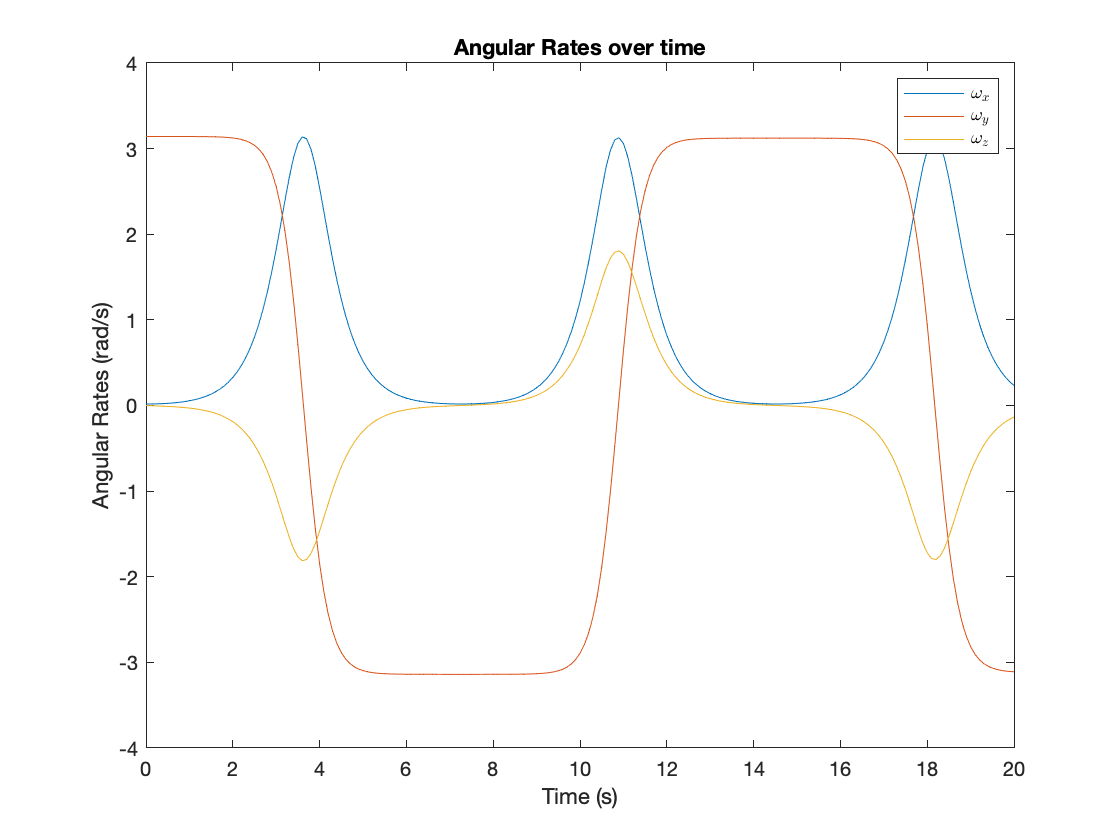

                      AngularRateODESolver(Imat2, w_initial2, tspan2)
% Angular Rates Plot
figure(3)
plot(tspan2, w2(:,1));
hold on
plot(tspan2, w2(:,2));
plot(tspan2, w2(:,3));
hold off;
title("Angular Rates over time");
xlabel("Time (s)");
ylabel("Angular Rates (rad/s)");
legend("$\omega_x$", "$\omega_y$", "$\omega_z$", 'Interpreter',"latex")

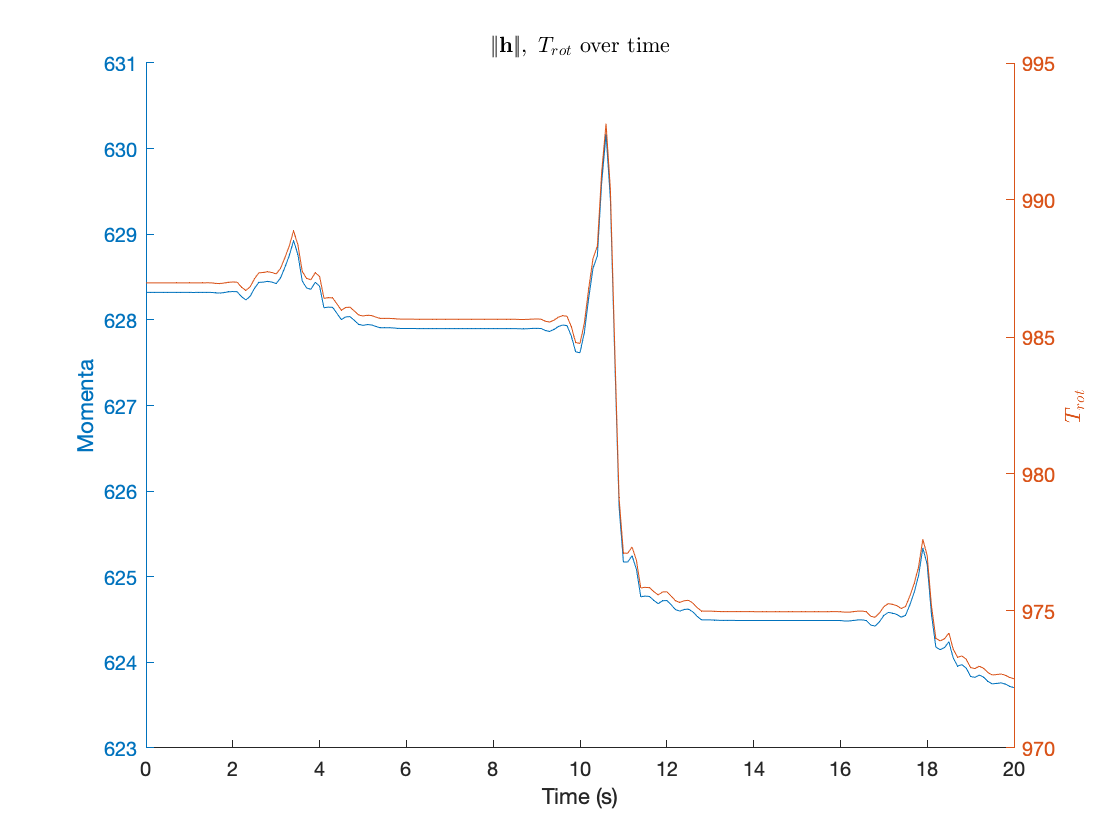

% Total Momentum and Kinetic Energy plot
figure(4)
hold on
yyaxis left
plot(tspan2,cell2mat(totMomentum2))
ylabel("Momenta")
xlabel("Time (s)");
yyaxis right
plot(tspan2, cell2mat(Trot2));
ylabel("$T_{rot}$", "Interpreter","latex")
hold off;
title("$|\!| \textbf{h} |\!|,\ T_{rot} $ over time","Interpreter","latex")

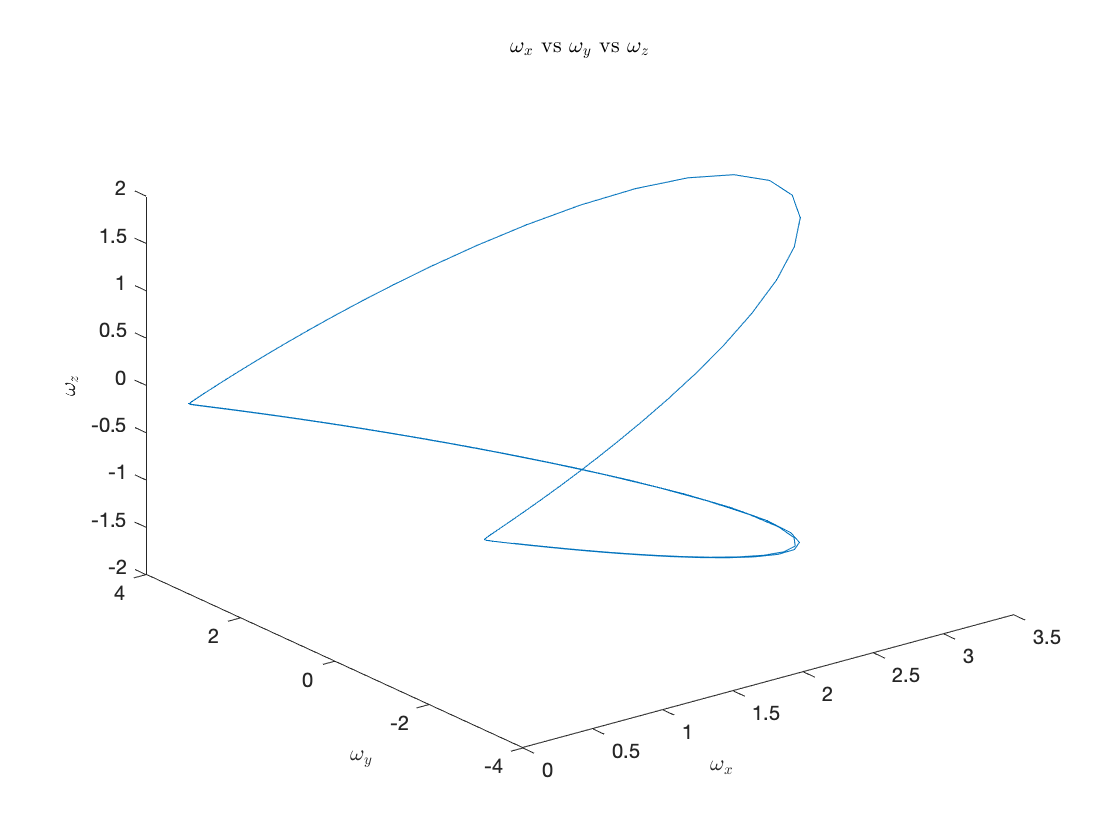

figure(5)
% As shown in class, I wanted to recreate the plot of w_x vs w_y vs w_z
plot3(w2(:,1), w2(:,2), w2(:,3));
title("$\omega_x$ vs $\omega_y$ vs $\omega_z$", "Interpreter","latex");
xlabel("$\omega_x$", "Interpreter", "latex");
ylabel("$\omega_y$", "Interpreter","latex");
zlabel("$\omega_z$", "Interpreter","latex");

## Function

Write a matlab function to solve this ODE, given initial conditions and a timespan

Output the following:

- Angular Rates ($\omega$'s)

- momenta along each axis

- Total momentum (magnitude) and kinetic energy

Solution:

function [w, momenta_matrix, totMomentum, Trot] = ...
                             AngularRateODESolver(Imat, w_init, tspan)
    % Inertia Values
    Ix = Imat(1,1);
    Iy = Imat(2,2);
    Iz = Imat(3,3);
    
    % differential equation here
    func = @(t,w) [((Iy - Iz)/Ix)*w(2)*w(3); 
                   ((Iz - Ix)/Iy)*w(1)*w(3);
                   ((Ix - Iy)/Iz)*w(1)*w(2)];
    
    % ode45 solver
    opts = odeset('AbsTol',1E-12);
    [t,w] = ode45(func, tspan, w_init, opts);
    
    for i = 1:length(tspan)
        momenta_matrix{:,i} = [Ix * w(i,1); Iy * w(i,2); Iz*w(i,3)];
        totMomentum{i} = norm(momenta_matrix{:,i},2); % Taking Euclidean 2-norm
        Trot{i} = 0.5*dot([w(i,1); w(i,2);w(i,3)], Imat*[w(i,1);w(i,2);w(i,3)]);
    end
end